Consider the following multi-objective problem:


$$\left\lbrace \begin{array}{ll}
\mathrm{minimize} & x_2 \;,-x_1 -2x_2 \\
s\ldotp t & x_1 \ge 0\\
 & x_2 \ge 0\\
 & x_1 +x_2 \le 5
\end{array}\right.$$


clear global;
close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

**a) Is it a convex problem? Why?**

We need to analyze the convexity of all the objective function and the feasible region:

- Objective Function

-     
$$f_1 \left(x\right)=x_2$$
 

-     
$$f_2 \left(x\right)={-x}_1 -2x_2$$


The objective function $f_1 \left(x\right)$ is a linear function, as same as $f_2 \left(x\right)$, which it means both of the objective functions are convex.

- Constraints 

-     
$$g_1 \left(x\right)=x_1 \ge 0$$


-     
$$g_2 \left(x\right)=x_2 \ge 0$$


-     
$$g_3 \left(x\right)=x_1 +x_2 \le 5$$


The constraints functions $g_1 \left(x\right)\;$and $g_2 \left(x\right)$ are both linear inequalities and the feasible region belong to the non-negative Castersian plane, and it means is convex set.  

The constraint function $g_3 \left(x\right)$ is also linear inequality constraint and the region is defined by $x_1 +x_2 =5$, $x_1 =0$and $x_2 =0$ makes a triangle set that is also convex.

Since all the objective functions and the feasible region are convex, we can confirm that this multi-objective optimization problem is convex.

% Definition of the objective functions and the constraints
objective_function_1 = @(x1,x2) x2;
objective_function_2 = @(x1,x2) -x1 - 2.*x2;
constraint_1 = @(x1,x2) -x1;
constraint_2 = @(x1,x2) -x2;
constraint_3 = @(x1,x2) x1 + x2 - 5;

% Creation of the grid with x1 and x2
x1 = linspace(0, 5, 100);
x2 = linspace(0, 5, 100);
[X1,X2] = meshgrid(x1,x2);

% Evaluate the objective functions and the feasible region
F1 = objective_function_1(X1,X2);
F2 = objective_function_2(X1,X2);
C1 = constraint_1(X1,X2);
C2 = constraint_2(X1,X2);
C3 = constraint_3(X1,X2);

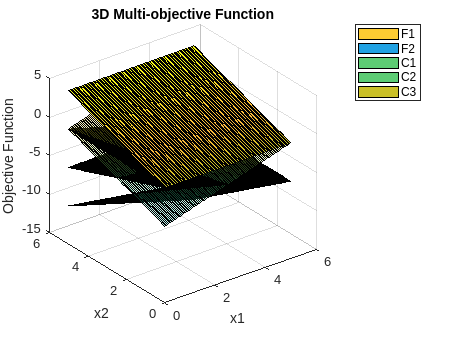

% Create a 3D plot
figure;
surf(X1,X2,F1);
hold on
surf(X1,X2,F2);
surf(X1,X2,C1, 'FaceAlpha', 0.3);
surf(X1,X2,C2, 'FaceAlpha', 0.3);
surf(X1,X2,C3, 'FaceAlpha', 0.3);

xlabel("x1");
ylabel("x2");
zlabel("Objective Function");

legend("F1", "F2", "C1", "C2", "C3");
title("3D Multi-objective Function");

view(3);

hold off

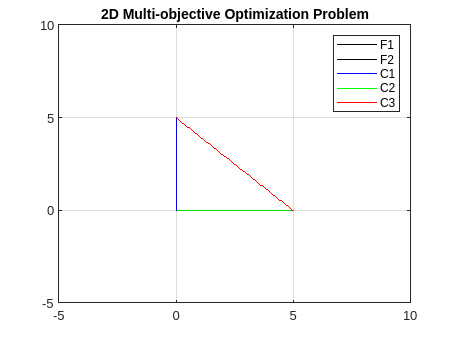

% Create 2D Plot
figure;
contour(X1,X2,F1, [0 0], 'k', 'LineWidth', 0.5);
hold on

contour(X1,X2,F2, [0 0], 'k', 'LineWidth', 0.5);
contour(X1,X2,C1, [0 0], 'b', 'LineWidth', 0.3);
contour(X1,X2,C2, [0 0], 'g', 'LineWidth', 0.3);
contour(X1,X2,C3, [0 0], 'r', 'LineWidth', 0.3);

legend('F1', 'F2', 'C1', 'C2', 'C3');
xlim([-5 10]);
ylim([-5 10]);
title('2D Multi-objective Optimization Problem');
grid on
hold off

**b) Do minima exist? Why?**

As we see on the previous point, we have a convex optimization problem and the feasible region is in the non-negative quadrant of the cartesian plane that is bounded by a triangular region. The Pareto frontier lies within this feasible region. 

This given multiobjective optimization problem does have  minima, which correspond to the points on the Pareto frontier within the feasible region defined by the constraints.

**c) Is the point (0, 2) a weak minimum? Why?**

First of all, we have

- Objective Function

-     
$$f_1 \left(x\right)=x_2$$
 

-     
$$f_2 \left(x\right)={-x}_1 -2x_2$$


Let's evaluate both objective functions at point (0,2):

x1 = 0;
x2 = 2;

fprintf("Evaluation at point (%2.2f %2.2f)", x1,x2);

Evaluation at point (0.00 2.00)

fprintf("F1: %2.2f",objective_function_1(x1,x2));

F1: 2.00

fprintf("F2: %2.2f",objective_function_2(x1,x2));

F2: -4.00

Now, let's consider nearby point that are within the feasible region and evaluate the objectives again with those points:

epsilon = 0.5;
phi = 0.5;

new_x1 = x1 + epsilon;
new_x2 = x2 - phi;

fprintf("Evaluation at point (%2.2f %2.2f)", new_x1,new_x2);

Evaluation at point (0.50 1.50)

fprintf("F1: %2.2f",objective_function_1(new_x1,new_x2));

F1: 1.50

fprintf("F2: %2.2f",objective_function_2(new_x1,new_x2));

F2: -3.50


new_x1 = x1 - epsilon;
new_x2 = x2 + phi;

fprintf("Evaluation at point (%2.2f %2.2f)", new_x1,new_x2);

Evaluation at point (-0.50 2.50)

fprintf("F1: %2.2f",objective_function_1(new_x1,new_x2));

F1: 2.50

fprintf("F2: %2.2f",objective_function_2(new_x1,new_x2));

F2: -4.50

It means, exists at least one better objective function values for at least one objective compare to the point (0,2). Therefore, this point is not a weak minima.

We can also check by solving the corresponding auxiliary problems:


$$\left\lbrace \begin{array}{ll}
\mathrm{maximize} & v\\
s\ldotp t & v\le \varepsilon_1 \\
 & f_i \left(x\right)+\varepsilon_i \le f_i \left(x^{\star } \right)\\
 & \varepsilon_i \ge 0\\
 & x\;\epsilon \;\Omega 
\end{array}\right.$$


Then $f\left(x^{\star } \right)=\left(2,4\right)$

The formula is transform to:


$$\left\lbrace \begin{array}{ll}
-\mathrm{minimize} & -v\\
s\ldotp t & v\le \varepsilon_1 \\
 & f_i \left(x\right)+\varepsilon_i \le f_i \left(x^{\star } \right)\\
 & \varepsilon_i \ge 0\\
 & x\;\epsilon \;\Omega 
\end{array}\right.$$


x = [0
     2];

C = [ 0  1
     -1 -2];

A = [-1  0
      0 -1
      1  1];

b = [0
     0
     5];

% Number of variables
n = size(C,2);
% Number of objective functions
p = size(C,1);
% Number of Constraints
m = size(A,1);

c = [zeros(n,1)
     zeros(p,1)
     -1 ];

P = [zeros(p,n) -eye(p) ones(p,1)
     C eye(p) zeros(p,1)
     A zeros(m,p) zeros(m,1)
     zeros(n,n) -eye(p) zeros(p,1) ];

q = [zeros(p,1)
     C*x
     b
     zeros(p,1)];

options = optimset('Display', 'off');
[optimal,v_weak_minimum] = linprog(c,P,q,[],[],[],[],[],options);

fprintf("Weak Minima at point (%2.2f %2.2f): %2.2f",x(1),x(2),v_weak_minimum);

Weak Minima at point (0.00 2.00): -1.50


fprintf("Optimal Solution (%2.2f %2.2f) \n", optimal(1), optimal(2));

Optimal Solution (4.50 0.50) 


fprintf("Slackness Variables (epsilon1 = %2.2f epsilon2 = %2.2f epsilon2 = %2.2f) \n", optimal(3), optimal(4), optimal(5));

Slackness Variables (epsilon1 = 1.50 epsilon2 = 1.50 epsilon2 = 1.50) 


**d) Find all the minima by using the scalarization method.**


$$\left\lbrace \begin{array}{ll}
\mathrm{minimize} & \sum_{i=1}^p \alpha_i {\;f}_i \left(x\right)\\
s\ldotp t & x\;\epsilon \;\Omega 
\end{array}\right.$$


With scalarization method, we have the optimization problem $P_{\alpha }$ is given by:


$$\left\lbrace \begin{array}{l}
\begin{array}{ll}
\mathrm{minimize} & \alpha_1 \left(x_2 \right)\;+\;\alpha_2 \left(-x_1 -2x_2 \right)\\
s\ldotp t & {-x}_1 \le 0\\
 & {-x}_2 \le 0\\
 & x_1 +x_2 \le 5
\end{array}
\end{array}\right.$$
 

with $\alpha_1 +\alpha_2 =1$

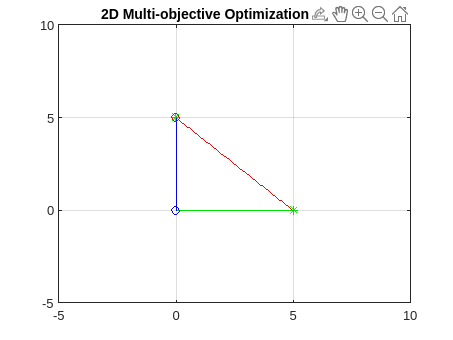

% x1*(alpha-1) + x2*(3*alpha-2) 

figure;
contour(X1,X2,F1, [0 0], 'k', 'LineWidth', 0.5);
hold on

contour(X1,X2,F2, [0 0], 'k', 'LineWidth', 0.5);
contour(X1,X2,C1, [0 0], 'b', 'LineWidth', 0.3);
contour(X1,X2,C2, [0 0], 'g', 'LineWidth', 0.3);
contour(X1,X2,C3, [0 0], 'r', 'LineWidth', 0.3);

xlim([-5 10]);
ylim([-5 10]);
title('2D Multi-objective Optimization Problem');
grid on


A = [-1  0
      0 -1
      1  1];
b = [0
     0
     5];

options = optimset("Display", "off");

for alpha = 0.001 : 0.001 : 0.999
    f = [alpha-1
         3*alpha-2];
    x = linprog(f,A,b,[],[],[],[],options);
    plot(x(1),x(2), 'g*', 'LineWidth', 1, 'DisplayName','Alpha');
end

% Alpha = 0
alpha = 0;
f = [alpha-1
     3*alpha-2];
x = linprog(f,A,b,[],[],[],[],options);
plot(x(1),x(2), 'ro', 'LineWidth', 1, 'DisplayName','Alpha 0');

% Alpha = 1
alpha = 1;
f = [alpha-1
     3*alpha-2];
x = linprog(f,A,b,[],[],[],[],options);
plot(x(1),x(2), 'bo', 'LineWidth', 1, 'DisplayName','Alpha 1');

hold off

**e) Find all the weak minima by using the scalarization method.**

**f) Find the ideal point.**

**g) Apply the goal method with L1**

**h) Apply the goal method with L2**

**i) Apply the goal method with L-infinity**